We have new data !

Well not so much new data. Old data correctly scaled. Let's try and see if it matches anything. 

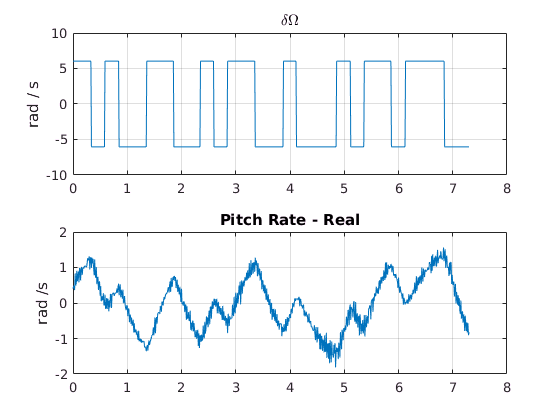

ol_data = load('dati_id_ol_scalati.mat');
load('quad_copter_models.mat');

figure()
    subplot 211
        plot(ol_data.t, ol_data.u);
        title('$\delta \Omega$', 'Interpreter', 'latex');
        ylabel('rad / s');
        
    subplot 212
        plot(ol_data.t, ol_data.yi); 
        title('Pitch Rate - Real');
        ylabel('rad /s');

Now we would like to see how the real data and our simulated data can compare.

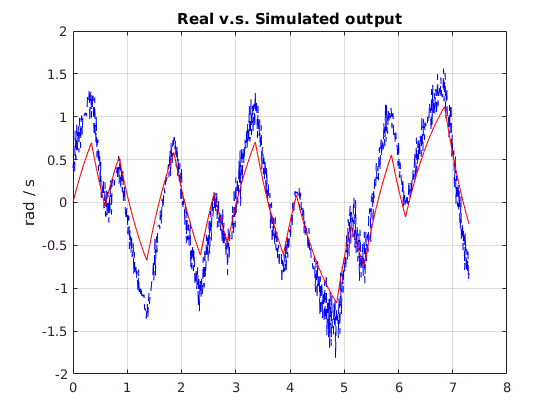

yi_sim = lsim(PitchRateModel, ol_data.u, ol_data.t);

figure()
    plot(ol_data.t, ol_data.yi, '--b', ol_data.t, yi_sim, 'r'); 
    title('Real v.s. Simulated output');
    ylabel('rad / s');